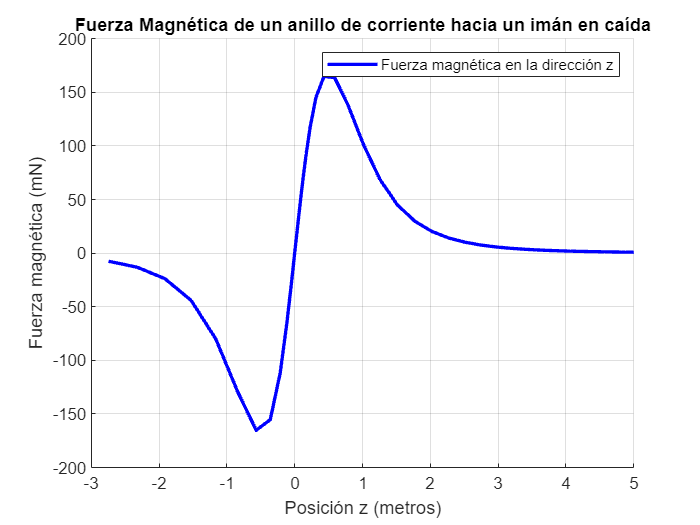

clear
clc
close all



corriente = 30; % la corriente I
mo = 4 * pi * 1e-7; %?
km = mo * corriente / (4*pi); %?
R = 1; %la Resistencia

%Calculo de la fuerza electromagnetica y graficacion

momentoMag = 10350; %momento magnético del imán 
m = 0.004; %Masa del iman en kg

w = m * -9.81; %El peso del iman

zi = 5; %Posicion z inicial iman

dt = 0.05; %cambio del tiempo

zm(1) = zi; %posicion z del iman, en este caso en la instancia 1
zmLibre(1) = zi; %posicion z del iman en caida libre, para comparacion

tt(1) = 0; %inicializacion del tiempo?
vm(1) = 0; %velocidad inicial del iman
vmLibre(1) = 0; %velocidad inicial del iman en caida libre
i = 1; %contador de instancias


while zm(i) > -3 %hasta que el iman llegue a la posicion z -3...

    Fm(i) = (6 * mo * corriente * R^2 * momentoMag * (zm(i) + 0.00001)) / (4 * ((zm(i) + 0.00001)^2 + R^2) ^ (5/2)); %fuerza magnetica
    F(i) = Fm(i) + w; %Fuerza total
    a = F(i) / m; %aceleracion

    zm(i+1)=zm(i)+vm(i)*dt+0.5*a*dt*dt;    %posicion actual del iman
 
    zmLibre(i+1)=zmLibre(i)+vmLibre(i)*dt-0.5*9.81*dt*dt;    %posicion actual del iman en caida libre

    vm(i+1)=(zm(i+1)-zm(i))/dt;       %velocidad actual del iman
    vmLibre(i+1)=(zmLibre(i+1)-zmLibre(i))/dt;  %velocidad actual del iman en caida libre

    i=i+1;

end

%Las graficas wiiii

hold on
plot(zm(1:length(Fm)), 1000 * Fm, '-b', 'LineWidth', 2) %por que 1000*Fm
plot([0,0], [-0.15, 0.15], '-.k', 'LineWidth', 2)

grid on

xlabel("Posición z (metros)")
ylabel("Fuerza magnética (mN)")
title("Fuerza Magnética de un anillo de corriente hacia un imán en caída")
legend("Fuerza magnética en la dirección z")

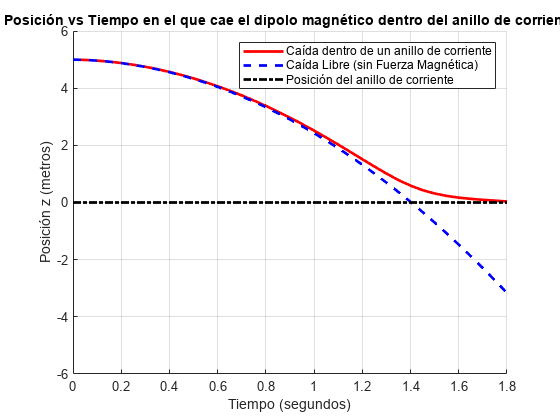


figure;
hold on
tt = 0: dt : (i - 1) * dt;
plot(tt, zm, '-r', 'LineWidth', 2)
plot(tt, zmLibre, '--b', 'LineWidth', 2)
plot([0, 1.8], [0,0], '-.k', 'LineWidth', 2)

grid on
xlabel("Tiempo (segundos)")
ylabel("Posición z (metros)")
title("Posición vs Tiempo en el que cae el dipolo magnético dentro del anillo de corriente")
legend("Caída dentro de un anillo de corriente", "Caída Libre (sin Fuerza Magnética)", "Posición del anillo de corriente")

axis([0 1.8 -6 6])